clear
clc
close all

x = 0:0.05:3*pi; t = sin(x.^2);

mse_1epoch = zeros(10, 6);
mse_14epoch = zeros(10, 6);
mse_985epoch = zeros(10, 6);

regress_1epoch = zeros(10, 6);
regress_14epoch = zeros(10, 6);
regress_100epoch = zeros(10, 6);

best_epoch_100 = zeros(10, 6);
best_epoch_14 = zeros(10, 6);

for j = 1:10
    
    %initialising networks
    gd_net = fitnet(30, 'traingd');
    gda_net = fitnet(30, 'traingda');
    cgf_net = fitnet(30, 'traincgf');
    cgp_net = fitnet(30, 'traincgp');
    bfg_net = fitnet(30, 'trainbfg');
    lm_net = fitnet(30, 'trainlm');
    
    nets = {gd_net, gda_net, cgf_net, cgp_net, bfg_net, lm_net};
    
    for i = 1:length(nets)      
        nets{i}.iw{1,1}=gd_net.iw{1,1}; %set the same weights and biases for the networks 
        nets{i}.lw{2,1}=gd_net.lw{2,1};
        
        nets{i}.b{1}=gd_net.b{1};
        nets{i}.b{2}=gd_net.b{2};   
    end
    
    %training networks with 1 epoch
    gd_net.trainParam.epochs=1;  
    gda_net.trainParam.epochs=1;
    cgf_net.trainParam.epochs=1;
    cgp_net.trainParam.epochs=1;
    bfg_net.trainParam.epochs=1;
    lm_net.trainParam.epochs=1;
    
    [gd_net, gd_tr] = train(gd_net, x, t);
    [gda_net, gda_tr] = train(gda_net, x, t);
    [cgf_net, cgf_tr] = train(cgf_net, x, t);
    [cgp_net, cgp_tr] = train(cgp_net, x, t);
    [bfg_net, bfg_tr] = train(bfg_net, x, t);
    [lm_net, lm_tr] = train(lm_net, x, t);
    
    %estimating targets using trained networks
    y_gd = gd_net(x);
    y_gda = gda_net(x);
    y_cgf = cgf_net(x);
    y_cgp = cgp_net(x);
    y_bfg = bfg_net(x);
    y_lm = lm_net(x);
    
    %assessing performances of networks with MSE
    gd_test_perf = gd_tr.best_tperf;
    gda_test_perf = gda_tr.best_tperf;
    cgf_test_perf = cgf_tr.best_tperf;
    cgp_test_perf = cgp_tr.best_tperf;
    bfg_test_perf = bfg_tr.best_tperf;
    lm_test_perf = lm_tr.best_tperf;
    test_perfs = [gd_test_perf gda_test_perf cgf_test_perf cgp_test_perf bfg_test_perf lm_test_perf];
    mse_1epoch(j,:) = test_perfs;
    
    %regression performance of networks
    r_gd = abs(regression(y_gd,t));
    r_gda = abs(regression(y_gda,t));
    r_cgf = abs(regression(y_cgf,t));
    r_cgp = abs(regression(y_cgp,t));
    r_bfg = abs(regression(y_bfg,t));
    r_lm = abs(regression(y_lm,t));
    regress_1 = [r_gd r_gda r_cgf r_cgp r_bfg r_lm];
    regress_1epoch(j,:) = regress_1;
end

average_regress = mean(regress_1epoch, 1);
average_mse = mean(mse_1epoch, 1);

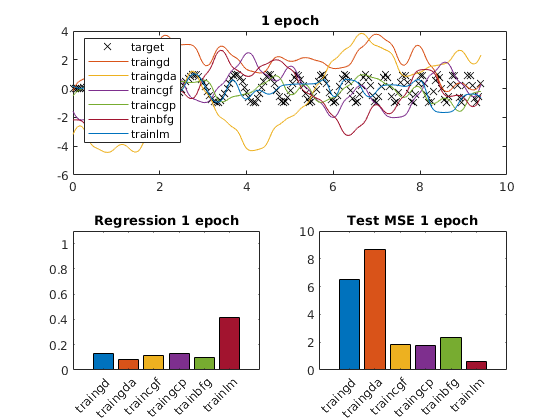

%plotting
newcolours = [0 0.4470 0.7410
              0.8500 0.3250 0.0980
              0.9290 0.6940 0.1250
              0.4940 0.1840 0.5560
              0.4660 0.6740 0.1880
              0.6350 0.0780 0.1840];

algorithm = {'traingd' 'traingda' 'traincgf' 'traingcp' 'trainbfg' 'trainlm'};

figure
subplot(2,2,1:2);
plot(x,t,'kx',x,y_gd,x,y_gda, x,y_cgf,x,y_cgp,x,y_bfg,x,y_lm); % plot the sine function and the output of the networks
title('1 epoch');
legend('target','traingd','traingda', 'traincgf','traincgp','trainbfg','trainlm','Location','northwest');

subplot(2,2,3);
b = bar(average_regress,'FaceColor','flat');
b.CData = newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.1]);
title('Regression 1 epoch');

subplot(2,2,4);
b = bar(average_mse,'FaceColor','flat');
b.CData = newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Test MSE 1 epoch');

colororder(newcolours); 

for j=1:10
    
    %initialising networks
    gd_net = fitnet(30, 'traingd');
    gda_net = fitnet(30, 'traingda');
    cgf_net = fitnet(30, 'traincgf');
    cgp_net = fitnet(30, 'traincgp');
    bfg_net = fitnet(30, 'trainbfg');
    lm_net = fitnet(30, 'trainlm');
    nets = {gd_net, gda_net, cgf_net, cgp_net, bfg_net, lm_net};
    
    for i = 1:length(nets)                        
        nets{i}.iw{1,1}=gd_net.iw{1,1}; %set the same weights and biases for the networks 
        nets{i}.lw{2,1}=gd_net.lw{2,1};
        
        nets{i}.b{1}=gd_net.b{1};
        nets{i}.b{2}=gd_net.b{2};  
    end
    
    %training networks with 14 epochs
    gd_net.trainParam.epochs=14;  
    gda_net.trainParam.epochs=14;
    cgf_net.trainParam.epochs=14;
    cgp_net.trainParam.epochs=14;
    bfg_net.trainParam.epochs=14;
    lm_net.trainParam.epochs=14;
    
    [gd_net, gd_tr] = train(gd_net, x, t);
    [gda_net, gda_tr] = train(gda_net, x, t);
    [cgf_net, cgf_tr] = train(cgf_net, x, t);
    [cgp_net, cgp_tr] = train(cgp_net, x, t);
    [bfg_net, bfg_tr] = train(bfg_net, x, t);
    [lm_net, lm_tr] = train(lm_net, x, t);
    
    %estimating targets using trained networks
    y_gd = gd_net(x);
    y_gda = gda_net(x);
    y_cgf = cgf_net(x);
    y_cgp = cgp_net(x);
    y_bfg = bfg_net(x);
    y_lm = lm_net(x);
    
    %assessing performances of networks with MSE
    gd_test_perf = gd_tr.best_tperf;
    gda_test_perf = gda_tr.best_tperf;
    cgf_test_perf = cgf_tr.best_tperf;
    cgp_test_perf = cgp_tr.best_tperf;
    bfg_test_perf = bfg_tr.best_tperf;
    lm_test_perf = lm_tr.best_tperf;
    test_perfs = [gd_test_perf gda_test_perf cgf_test_perf cgp_test_perf bfg_test_perf lm_test_perf];
    mse_14epoch(j,:) = test_perfs;
    
    %regression performance of networks
    r_gd = abs(regression(y_gd,t));
    r_gda = abs(regression(y_gda,t));
    r_cgf = abs(regression(y_cgf,t));
    r_cgp = abs(regression(y_cgp,t));
    r_bfg = abs(regression(y_bfg,t));
    r_lm = abs(regression(y_lm,t));
    regress_14 = [r_gd r_gda r_cgf r_cgp r_bfg r_lm];
    regress_14epoch(j,:) = regress_14;
    
    
    epoch_gd = gd_tr.best_epoch;
    epoch_gda = gda_tr.best_epoch;
    epoch_cgf = cgf_tr.best_epoch;
    epoch_cgp = cgp_tr.best_epoch;
    epoch_bfg = bfg_tr.best_epoch;
    epoch_lm = lm_tr.best_epoch;
    best_epochs = [epoch_gd epoch_gda epoch_cgf epoch_cgp epoch_bfg epoch_lm];
    best_epoch_14(j,:) = best_epochs;
end

average_regress = mean(regress_14epoch, 1);
average_mse = mean(mse_14epoch, 1);
average_epochs = mean(best_epoch_14, 1);

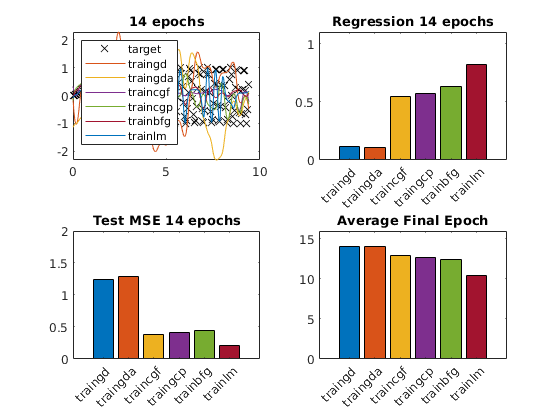

% Plotting
newcolours = [0 0.4470 0.7410
              0.8500 0.3250 0.0980
              0.9290 0.6940 0.1250
              0.4940 0.1840 0.5560
              0.4660 0.6740 0.1880
              0.6350 0.0780 0.1840];

algorithm = {'traingd' 'traingda' 'traincgf' 'traingcp' 'trainbfg' 'trainlm'};

figure
subplot(2,2,1);
plot(x,t,'kx',x,y_gd,x,y_gda, x,y_cgf,x,y_cgp,x,y_bfg,x,y_lm); % plot the sine function and the output of the networks
title('14 epochs');
legend('target','traingd','traingda', 'traincgf','traincgp','trainbfg','trainlm','Location','northwest');

subplot(2,2,2);
b = bar(average_regress,'FaceColor','flat');
b.CData = newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.1]);
title('Regression 14 epochs');

subplot(2,2,3);
b = bar(average_mse,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 2]);
title('Test MSE 14 epochs');

subplot(2,2,4);
b = bar(average_epochs,'FaceColor','flat');
b.CData = newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 16]);
title('Average Final Epoch');

colororder(newcolours); 

for j=1:10
    
    %initialising networks
    gd_net = fitnet(30, 'traingd');
    gda_net = fitnet(30, 'traingda');
    cgf_net = fitnet(30, 'traincgf');
    cgp_net = fitnet(30, 'traincgp');
    bfg_net = fitnet(30, 'trainbfg');
    lm_net = fitnet(30, 'trainlm');
    
    nets = {gd_net, gda_net, cgf_net, cgp_net, bfg_net, lm_net};
    
    for i = 1:length(nets)      
        nets{i}.iw{1,1}=gd_net.iw{1,1}; %set the same weights and biases for the networks 
        nets{i}.lw{2,1}=gd_net.lw{2,1};
        
        nets{i}.b{1}=gd_net.b{1};
        nets{i}.b{2}=gd_net.b{2};   
    end
    
    %training networks with 985 epochs
    gd_net.trainParam.epochs=100;  
    gda_net.trainParam.epochs=100;
    cgf_net.trainParam.epochs=100;
    cgp_net.trainParam.epochs=100;
    bfg_net.trainParam.epochs=100;
    lm_net.trainParam.epochs=100;
    
    [gd_net, gd_tr] = train(gd_net, x, t);
    [gda_net, gda_tr] = train(gda_net, x, t);
    [cgf_net, cgf_tr] = train(cgf_net, x, t);
    [cgp_net, cgp_tr] = train(cgp_net, x, t);
    [bfg_net, bfg_tr] = train(bfg_net, x, t);
    [lm_net, lm_tr] = train(lm_net, x, t);
    
    %estimating targets using trained networks
    y_gd = gd_net(x);
    y_gda = gda_net(x);
    y_cgf = cgf_net(x);
    y_cgp = cgp_net(x);
    y_bfg = bfg_net(x);
    y_lm = lm_net(x);
    
    %assessing performances of networks with MSE
    gd_test_perf = gd_tr.best_tperf;
    gda_test_perf = gda_tr.best_tperf;
    cgf_test_perf = cgf_tr.best_tperf;
    cgp_test_perf = cgp_tr.best_tperf;
    bfg_test_perf = bfg_tr.best_tperf;
    lm_test_perf = lm_tr.best_tperf;
    test_perfs = [gd_test_perf gda_test_perf cgf_test_perf cgp_test_perf bfg_test_perf lm_test_perf];
    mse_100epoch(j,:) = test_perfs;
    
    %regression performance of networks
    r_gd = abs(regression(y_gd,t));
    r_gda = abs(regression(y_gda,t));
    r_cgf = abs(regression(y_cgf,t));
    r_cgp = abs(regression(y_cgp,t));
    r_bfg = abs(regression(y_bfg,t));
    r_lm = abs(regression(y_lm,t));
    regress_100 = [r_gd r_gda r_cgf r_cgp r_bfg r_lm];
    regress_100epoch(j,:) = regress_100;
    
    epoch_gd = gd_tr.best_epoch;
    epoch_gda = gda_tr.best_epoch;
    epoch_cgf = cgf_tr.best_epoch;
    epoch_cgp = cgp_tr.best_epoch;
    epoch_bfg = bfg_tr.best_epoch;
    epoch_lm = lm_tr.best_epoch;
    best_epochs = [epoch_gd epoch_gda epoch_cgf epoch_cgp epoch_bfg epoch_lm];
    best_epoch_100(j,:) = best_epochs;
end

average_regress = mean(regress_100epoch, 1);
average_mse = mean(mse_100epoch, 1);
average_epochs = mean(best_epoch_100, 1);

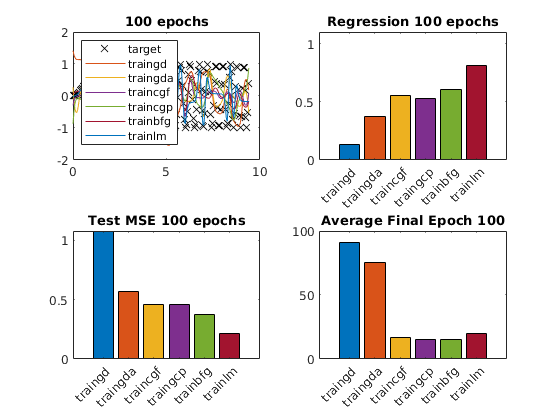

%plotting
figure
subplot(2,2,1);
plot(x,t,'kx',x,y_gd,x,y_gda, x,y_cgf,x,y_cgp,x,y_bfg,x,y_lm); % plot the sine function and the output of the networks
title('100 epochs');
legend('target','traingd','traingda', 'traincgf','traincgp','trainbfg','trainlm','Location','northwest');

subplot(2,2,2);
b = bar(average_regress,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.1]);
title('Regression 100 epochs');

subplot(2,2,3);
b = bar(average_mse,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Test MSE 100 epochs');

subplot(2,2,4);
b = bar(average_epochs,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Average Final Epoch 100');

colororder(newcolours);